clear

data1 = readmatrix('NormSegDens_testomp.txt');
data2 = readmatrix('NormSegDens_n20test.txt');
data3 = readmatrix('NormSegDens_n26test.txt');

x1 = data1(:, 1);
y1 = data1(:, 2);
x2 = data2(:,1);
y2 = data2(:,2);
x3 = data3(:,1);
y3 = data3(:,2);

X = linspace(0,1,200)';
integral_approx = trapz(X,y1)

integral_approx = 0.9989

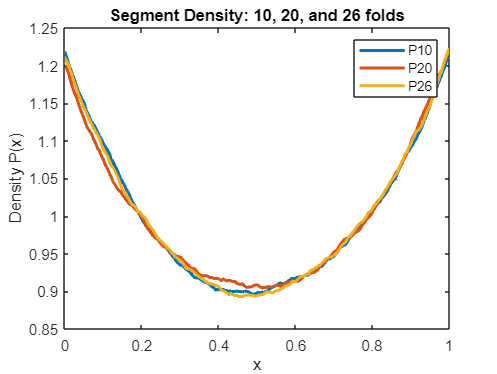


plot(x1,y1,LineWidth=2);
hold on; 
plot(x2,y2,LineWidth=2);
plot(x3,y3,LineWidth=2);
xlabel('x');
ylabel('Density P(x)');
title('Segment Density: 10, 20, and 26 folds');
legend('P10', 'P20', "P26");
% ylim([5*10^-3,8*10^-3]);
hold off; 


% TODO: exclude p(x) = 0 points...